# **Lab3 Position control of a DC servomotor with resonant load**

## 2.1 - Define Param

% load variables in workspace of LAB0 (parameters according to motor 8)
load params_estimated_LAB0.mat
load params_resonant_case.mat
sens.enc.pulse2deg = 360/2000;  % in lab da cambiare in 360/4096

Beq = Beq_hat ;                      % mot.B + mld.B/gbox.N^2;    
Jeq = mot.J + mld.Jh/gbox.N^2;
mld.Bb = 3.4e-3;  %Jb = 1.4e-3;
k_spring = 0.83;

Req = mot.R + sens.curr.Rs;

km = (drv.dcgain*mot.Kt)/(Req*Beq + mot.Kt*mot.Ke);
Tm = (Req*Jeq)/(Req*Beq + mot.Kt*mot.Ke);

## 2.2 - Position PID control

% open simulink model
open_system('PositionPIDcontrol.slx');
set_param('PositionPIDcontrol', 'SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

#### point 1

%compute Transfer function of the new plant
s = tf('s');
D_tau_prime = Jeq*mld.Jb*s^3 + (Jeq*mld.Bb + mld.Jb*Beq)*s^2 + (Beq*mld.Bb + k_spring*(Jeq + mld.Jb/gbox.N^2))*s + k_spring*(Beq + mld.Bb/gbox.N^2);
Num  =  drv.dcgain * mot.Kt * (mld.Jb*s^2 + mld.Bb*s + k_spring);
Den  = gbox.N * s * (Req*D_tau_prime + mot.Kt*mot.Ke*(mld.Jb*s^2 + mld.Bb*s + k_spring));
Pu_thh =  Num / Den;

%introduce specifications
spec.ts5    =  0.85;         % Settling-time
spec.Mp     =  0.3;          % Overshoot
spec.damp   =  log(1/spec.Mp) / (sqrt(pi^2+(log(1/spec.Mp))^2));
spec.wn     =  3 / (spec.damp*spec.ts5);
ctrl.alpha  =  4;

%compute PID gains
ctrl.w_gc = 3/(spec.damp*spec.ts5);
ctrl.phi_m = atan(2*spec.damp/(sqrt(sqrt(1+4*spec.damp^4)-2*spec.damp^2))); 
ctrl.T_L = 1/(10*ctrl.w_gc);
ctrl.T_w = spec.ts5/5; 

ctrl.frq_resp = freqresp(Pu_thh,ctrl.w_gc);

ctrl.Delta_K = 1/(abs(ctrl.frq_resp));
ctrl.Delta_phi = -pi + ctrl.phi_m - angle(ctrl.frq_resp);

ctrl.Kp = ctrl.Delta_K*cos(ctrl.Delta_phi);
ctrl.Td = (tan(ctrl.Delta_phi)+sqrt((tan(ctrl.Delta_phi))^2 +4/ctrl.alpha))  /(2*ctrl.w_gc);
ctrl.Ti = ctrl.alpha*ctrl.Td;

ctrl.Ki = ctrl.Kp/ctrl.Ti;
ctrl.Kd = ctrl.Kp*ctrl.Td;

#### point 2

% define step size
step_size = 50;

% run simulation - without AWU
ctrl.Kw = 0;
sim('PositionPIDcontrol');
data.noawu.step1.t    = MotorData.time;
data.noawu.step1.thh  = MotorData.signals(1).values;

% run simulation - with AWU - tentative #1
ctrl.Kw = 1/ctrl.T_w;
sim('PositionPIDcontrol');
data.awu.step1.t    = MotorData.time;
data.awu.step1.thh  = MotorData.signals(1).values;

% run simulation - with AWU - tentative #2
ctrl.Kw = 8;       
sim('PositionPIDcontrol');
data.awu2.step1.t    = MotorData.time;
data.awu2.step1.thh  = MotorData.signals(1).values;


% define step size
step_size = 120;

% run simulation - without AWU
ctrl.Kw = 0;
sim('PositionPIDcontrol');
data.noawu.step2.t    = MotorData.time;
data.noawu.step2.thh  = MotorData.signals(1).values;

% run simulation - with AWU - tentative #1
ctrl.Kw = 1/ctrl.T_w;
sim('PositionPIDcontrol');
data.awu.step2.t    = MotorData.time;
data.awu.step2.thh  = MotorData.signals(1).values;

% run simulation - with AWU - tentative #2
ctrl.Kw = 8;       
sim('PositionPIDcontrol');
data.awu2.step2.t    = MotorData.time;
data.awu2.step2.thh  = MotorData.signals(1).values;

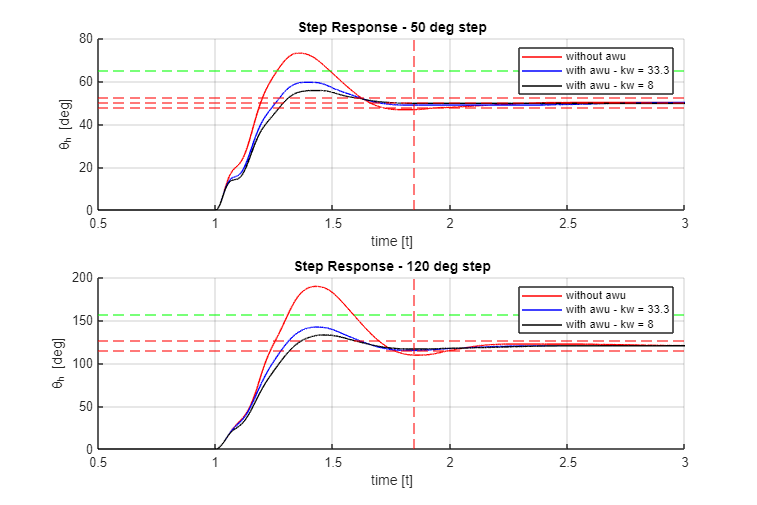

figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1)
step_size = 50;
hold on;
plot(data.noawu.step1.t, data.noawu.step1.thh,'r');
plot(data.awu.step1.t, data.awu.step1.thh,'b');
plot(data.awu2.step1.t, data.awu2.step1.thh,'k');

title('Step Response - 50 deg step')
xlabel('time [t]');
ylabel('\theta_h [deg]');
grid on;
yline(step_size,'r--')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size * 1.3, 'g--')
xline(1+0.85,'r--')
legend('without awu','with awu - kw = 33.3','with awu - kw = 8')
xlim([0.5,3])
hold off;

subplot(2,1,2)
step_size = 120;
hold on;
plot(data.noawu.step2.t, data.noawu.step2.thh,'r');
plot(data.awu.step2.t, data.awu.step2.thh,'b');
plot(data.awu2.step2.t, data.awu2.step2.thh,'k');

title('Step Response - 120 deg step')
xlabel('time [t]');
ylabel('\theta_h [deg]');
grid on;
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size * 1.3, 'g--')
xline(1+0.85,'r--')
legend('without awu','with awu - kw = 33.3','with awu - kw = 8')
xlim([0.5,3])
hold off;

data.noawu.step1.resp = stepinfo(data.noawu.step1.thh,data.noawu.step1.t);
data.awu.step1.resp = stepinfo(data.awu.step1.thh,data.awu.step1.t);
data.awu2.step1.resp = stepinfo(data.awu2.step1.thh,data.awu2.step1.t);
data.noawu.step2.resp = stepinfo(data.noawu.step2.thh,data.noawu.step2.t);
data.awu.step2.resp = stepinfo(data.awu.step2.thh,data.awu.step2.t);
data.awu2.step2.resp = stepinfo(data.awu2.step2.thh,data.awu2.step2.t);

% display results
response = {'50 deg no AWU';'50 deg Kw = 33.3';'50 deg Kw = 8';'120 deg no AWU';'120 deg Kw = 33.3';'120 deg Kw = 8'};
settlingTime = {data.noawu.step1.resp.SettlingTime; data.awu.step1.resp.SettlingTime; data.awu2.step1.resp.SettlingTime;
                data.noawu.step2.resp.SettlingTime; data.awu.step2.resp.SettlingTime; data.awu2.step2.resp.SettlingTime};
overshoot = {data.noawu.step1.resp.Overshoot; data.awu.step1.resp.Overshoot; data.awu2.step1.resp.Overshoot;
             data.noawu.step2.resp.Overshoot; data.awu.step2.resp.Overshoot; data.awu2.step2.resp.Overshoot};

table(response,settlingTime,overshoot)

ans = 6×3 table
          response           settlingTime     overshoot 
    _____________________    ____________    ___________

    {'50 deg no AWU'    }     {[2.2088]}     {[45.6438]}
    {'50 deg Kw = 33.3' }     {[2.4863]}     {[18.5268]}
    {'50 deg Kw = 8'    }     {[1.6546]}     {[11.0679]}
    {'120 deg no AWU'   }     {[2.0602]}     {[57.6991]}
    {'120 deg Kw = 33.3'}     {[2.0640]}     {[18.0844]}
    {'120 deg Kw = 8'   }     {[2.1125]}     {[10.3543]}


## 2.3 Position state-space control using eigenvalues placement design methods

#### point 1 (Nominal tracking)

open_system('nominal_tracking.slx')
set_param('nominal_tracking','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

% define H1 filter
H1.wc = 2*pi*50;   
H1.d = 1/sqrt(2);
H1s = tf([H1.wc^2,0],[1, 2*H1.d*H1.wc, H1.wc^2]);
[numH1, denH1] = tfdata(H1s,'v');

%   non-encapsulated SS data
A = [0, 0, 1, 0; 
     0, 0, 0, 1;
    -k_spring/(gbox.N^2 * Jeq), k_spring/(gbox.N^2 * Jeq), (-1/ Jeq) * (Beq + mot.Kt*mot.Ke/Req), 0;
     k_spring/mld.Jb, -k_spring/mld.Jb, 0, -mld.Bb/mld.Jb ];

B = [0; 0; mot.Kt* drv.dcgain / (gbox.N * Jeq * Req); 0]; 

B_d = [0; 0; -1/ (gbox.N^2*Jeq); 0];

Btot = [B, B_d];

C = [1, 0, 0, 0];

D = 0;

%   encapsulated SS data
sys = ss(A, B, C, D);

%   matrix: beam --> displacement
T = [1,0,0,0;
     1,1,0,0;
     0,0,1,0;
     0,0,1,1];

Ad = inv(T)*A*T;
Bd = inv(T)*B;
Bd_d = inv(T)*B_d;
Bdtot = [Bd, Bd_d];
Cd = C*T;
Dd = D;

%  compute N_x, N_u
S = [Ad,Bdtot;Cd,0,0];
b=[0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) -N(3) -N(4)];
N_u = N(5);

#### point 2

%run simulation
step_size = 50;

%Eigenvalues - tentative #1
phi = atan(sqrt(1-spec.damp^2)/spec.damp);
lambda1 = spec.wn*exp(j*(-pi+phi));
lambda2 = conj(lambda1);
lambda3 = spec.wn*exp(j*(-pi+phi/2));
lambda4 = conj(lambda3);

p = [lambda1, lambda2, lambda3, lambda4];
K = place(Ad,Bd,p);

sim('nominal_tracking.slx');
data.nominal.poles1.t    = MotorData.time;
data.nominal.poles1.thh  = MotorData.signals(1).values;

%Eigenvalues - tentative #2
phi = atan(sqrt(1-spec.damp^2)/spec.damp);
lambda1 = spec.wn*exp(j*(-pi+phi))*2;
lambda2 = conj(lambda1);
lambda3 = spec.wn*exp(j*(-pi+phi/2))*2;
lambda4 = conj(lambda3);
 
p = [lambda1, lambda2, lambda3, lambda4];
K = place(Ad,Bd,p);

sim('nominal_tracking.slx');
data.nominal.poles2.t    = MotorData.time;
data.nominal.poles2.thh  = MotorData.signals(1).values;

%Eigenvalues - tentative #3
phi = atan(sqrt(1-spec.damp^2)/spec.damp);
lambda1 = spec.wn*exp(j*(-pi+phi))*3;
lambda2 = conj(lambda1);
lambda3 = spec.wn*exp(j*(-pi+phi/2))*3;
lambda4 = conj(lambda3);
 
p = [lambda1, lambda2, lambda3, lambda4];
K = place(Ad,Bd,p);

sim('nominal_tracking.slx');
data.nominal.poles3.t    = MotorData.time;
data.nominal.poles3.thh  = MotorData.signals(1).values;

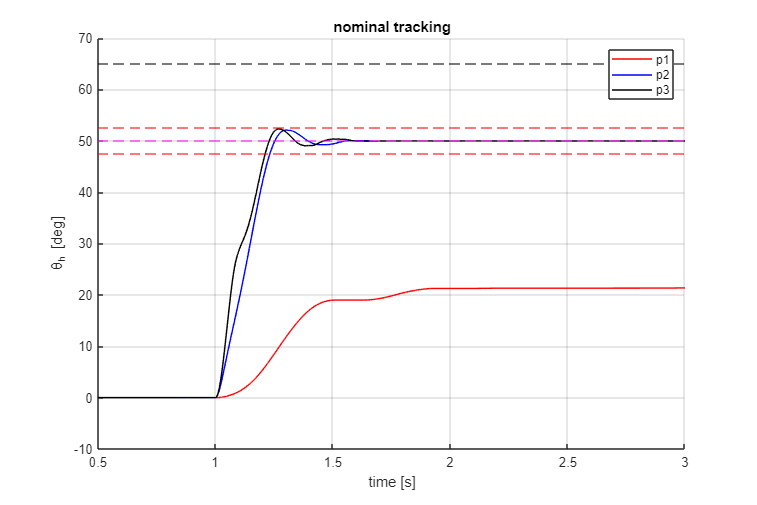

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.nominal.poles1.t,data.nominal.poles1.thh,'r');
plot(data.nominal.poles2.t,data.nominal.poles2.thh,'b');
plot(data.nominal.poles3.t,data.nominal.poles3.thh,'k');

yline(step_size,'m--')
yline(step_size*0.95,'r--')
yline(step_size*1.05,'r--')
yline(step_size*1.3,'k--')
hold off;
legend('p1','p2','p3');
xlabel('time [s]');
ylabel('\theta_h [deg]');
xlim([0.5,3])
title('nominal tracking')
grid on

data.nominal.poles2.resp = stepinfo(data.nominal.poles2.thh,data.nominal.poles2.t);
data.nominal.poles3.resp = stepinfo(data.nominal.poles3.thh,data.nominal.poles3.t);
% display results
response = {'p2';'p3'};
settlingTime = {data.nominal.poles2.resp.SettlingTime;data.nominal.poles3.resp.SettlingTime};
overshoot = {data.nominal.poles2.resp.Overshoot;data.nominal.poles3.resp.Overshoot};

table(response,settlingTime,overshoot)

ans = 2×3 table
    response    settlingTime    overshoot 
    ________    ____________    __________

     {'p2'}      {[1.3638]}     {[4.2485]}
     {'p3'}      {[1.3183]}     {[4.6980]}


#### point 3  (Robust tracking)

open_system('robust_tracking_integral.slx')
set_param('robust_tracking_integral','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

%space model with augmented state
zer = zeros(4,1);
Ae=[0 Cd; zer Ad];
Be=[0; Bd];
Ce=[Cd 0];

#### point 4


%run simulation
step_size = 50;

% Eigenvalues - tentative #1
lambda1 = spec.wn*exp(j*(-pi+phi));
lambda2 = conj(lambda1);
lambda3 = spec.wn*exp(j*(-pi+phi/2));
lambda4 = conj(lambda3);
lambda5 = -spec.wn;

p = [lambda1 lambda2 lambda3 lambda4 lambda5];
Ke = place(Ae,Be,p);
K2 = [Ke(2) Ke(3) Ke(4) Ke(5)];
Ki = Ke(1);

ctrl.Kw = 0;

sim('robust_tracking_integral.slx');
data.robust.poles1.t    = MotorData.time;
data.robust.poles1.thh  = MotorData.signals(1).values;

% Eigenvalues - tentative #2
lambda1 = spec.wn*exp(j*(-pi+phi))*2;
lambda2 = conj(lambda1);
lambda3 = spec.wn*exp(j*(-pi+phi/2))*2;
lambda4 = conj(lambda3);
lambda5 = -spec.wn*3;

p = [lambda1 lambda2 lambda3 lambda4 lambda5];
Ke = place(Ae,Be,p);
K2 = [Ke(2) Ke(3) Ke(4) Ke(5)];
Ki = Ke(1);

ctrl.Kw = 0;

sim('robust_tracking_integral.slx');
data.robust.poles2.t    = MotorData.time;
data.robust.poles2.thh  = MotorData.signals(1).values;

%a nti windup - tentative #3
ctrl.Kw = 2;

sim('robust_tracking_integral.slx');
data.robust.poles2.awu.t    = MotorData.time;
data.robust.poles2.awu.thh  = MotorData.signals(1).values;

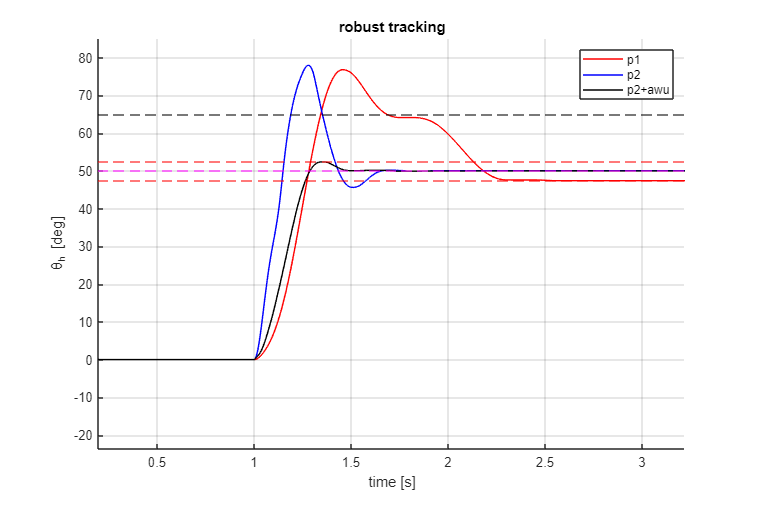


figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.robust.poles1.t,data.robust.poles1.thh,'r');
plot(data.robust.poles2.t,data.robust.poles2.thh,'b');
plot(data.robust.poles2.awu.t,data.robust.poles2.awu.thh,'k');

yline(step_size,'m--')
yline(step_size*0.95,'r--')
yline(step_size*1.05,'r--')
yline(step_size*1.3,'k--')
hold off;
legend('p1','p2','p2+awu');
xlabel('time [s]');
ylabel('\theta_h [deg]');
xlim([0.5,3])
title('robust tracking')
grid on

data.robust.poles1.resp = stepinfo(data.robust.poles1.thh,data.robust.poles1.t);
data.robust.poles2.resp = stepinfo(data.robust.poles2.thh,data.robust.poles2.t);
data.robust.poles2.awu.resp = stepinfo(data.robust.poles2.awu.thh,data.robust.poles2.awu.t);
% display results
response = {'p1';'p2';'p2+awu'};
settlingTime = {data.robust.poles1.resp.SettlingTime;data.robust.poles2.resp.SettlingTime;data.robust.poles2.awu.resp.SettlingTime};
overshoot = {data.robust.poles1.resp.Overshoot;data.robust.poles2.resp.Overshoot;data.robust.poles2.awu.resp.Overshoot};

table(response,settlingTime,overshoot)

ans = 3×3 table
     response     settlingTime     overshoot 
    __________    ____________    ___________

    {'p1'    }     {[2.2022]}     {[59.0389]}
    {'p2'    }     {[1.6142]}     {[55.9787]}
    {'p2+awu'}     {[1.4306]}     {[ 4.9303]}


## 2.4 - Position state-space control using LQR methods (cambiare ramo da b a d)

#### point 1 (root locus method)

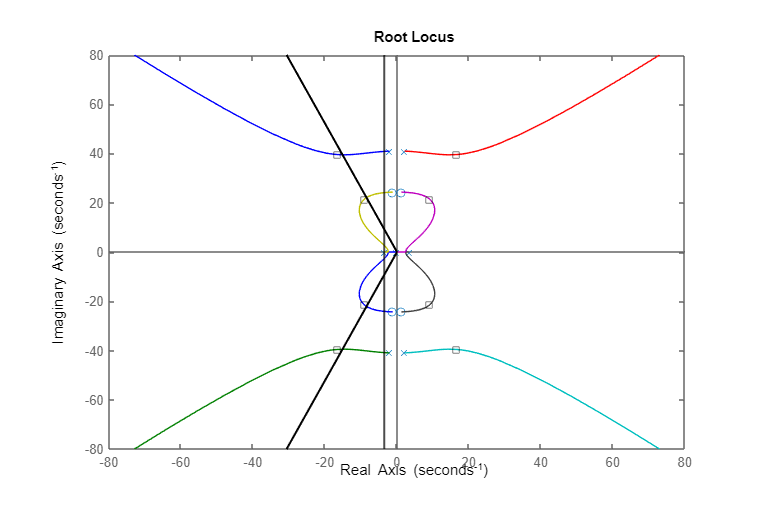

sysG = ss(Ad,Bd,Cd,0);
sysGp = ss(-Ad,-Bd,Cd,0);

%loop transfer function
G_tf = sysG*sysGp.';
sigma = -spec.wn*spec.damp;
sigma_max = -3/spec.ts5;

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on
rlocus(G_tf)
[r,k] = rlocus(G_tf,3800);
plot([r],'ks');
xline(sigma_max,'k','LineWidth',1.5);
plot([0,-cos(phi)*1000],[0,sin(phi)*1000],'k','LineWidth',1.5);
plot([0,-cos(phi)*1000],[0,-sin(phi)*1000],'k','LineWidth',1.5);
xlim([-80,80]);
ylim([-80,80]);
hold off;

% value found k = 3800 
k = 3800;
r = 1/k;
K = lqry(sysG,1,r);

#### point 2

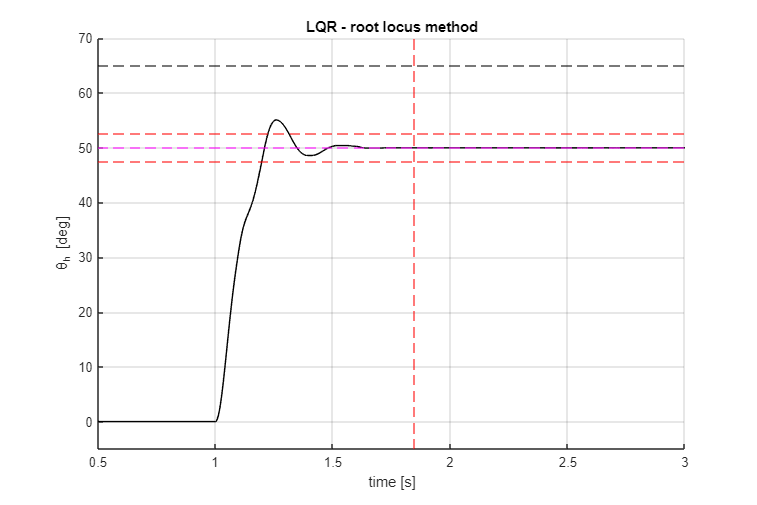

%run simulation
step_size = 50;
sim('nominal_tracking.slx');
data.nominal.LQR1.t    = MotorData.time;
data.nominal.LQR1.thh  = MotorData.signals(1).values;

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.nominal.LQR1.t,data.nominal.LQR1.thh,'k');
yline(step_size,'m--')
hold off;
xlabel('time [s]');
ylabel('\theta_h [deg]');
title('LQR - root locus method')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size*1.3,'k--')
xline(1.85,'r--')
xlim([0.5,3])
ylim([-5,70])
grid on;

#### point 3 (Bryson's rule)

step_size = 50;

% max deviations
th_h_bar = 0.3*step_size*deg2rad;
th_d_bar = (pi/36);
u_bar = 10;

Q = diag([1/th_h_bar^2   1/th_d_bar^2 0 0]);
R = 1/u_bar^2;
K = lqr(sysG,Q,R);

#### point 4

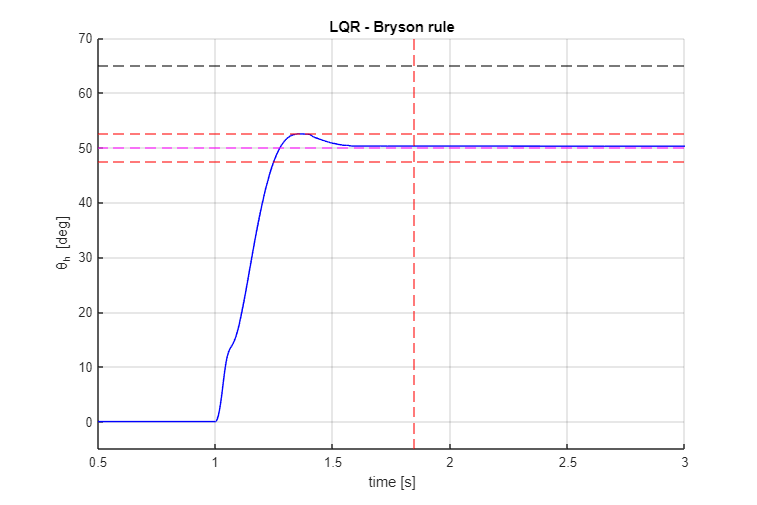

%run simulation
sim('nominal_tracking.slx');
data.nominal.LQR2.t    = MotorData.time;
data.nominal.LQR2.thh  = MotorData.signals(1).values;

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.nominal.LQR2.t,data.nominal.LQR2.thh,'b');
yline(50,'m--')
hold off;
xlabel('time [s]');
ylabel('\theta_h [deg]');
title('LQR - Bryson rule')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size*1.3,'k--')
xline(1.85,'r--')
xlim([0.5,3])
ylim([-5,70])
grid on;

#### point 5

%open simulink
open_system('robust_tracking_integral.slx')
set_param('robust_tracking_integral','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

%space model with augmented state
zer = zeros(4,1);
Ae=[0 Cd; zer Ad];
Be=[0; Bd];
Ce=[Cd 0];

ctrl.Kw = 0;

sysGe = ss(Ae,Be,Ce,0);
sysGep = ss(-Ae,-Be,Ce,0);

%loop transfer function
Ge_tf = sysGe*sysGep.' ;
sigma = -spec.wn*spec.damp

sigma = -3.5294

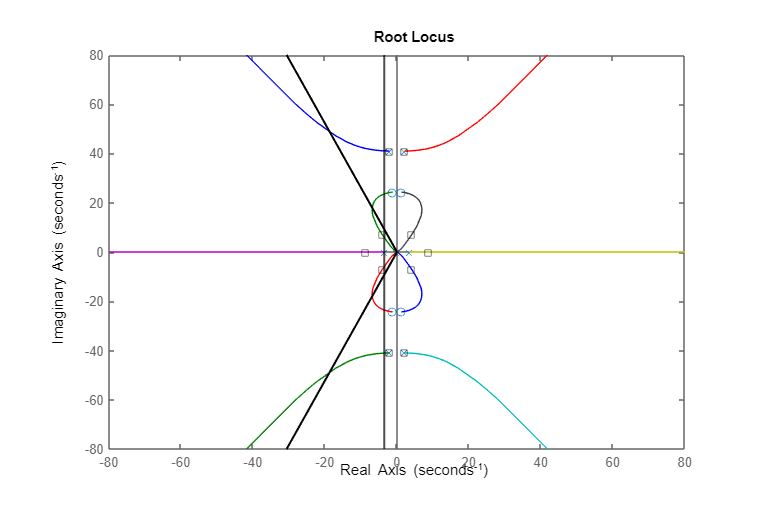

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on
rlocus(Ge_tf)
[r,k] = rlocus(Ge_tf,3.52e+03);
plot([r],'ks');
xline(sigma,'k','LineWidth',1.5)
plot([0 -cos(phi)*1000],[0 sin(phi)*1000],"k",'LineWidth',1.5)
plot([0 -cos(phi)*1000],[0 -sin(phi)*1000],"k",'LineWidth',1.5)
xlim([-80,80]);
ylim([-80,80]);
hold off

%for move the high frequency poles : k = 2.01e+07
%for move the low frequency poles : k = 3.52e+03
K = lqry(sysGe,1,1/k)

K =    59.3296   14.0592    8.1656    1.3454    0.8510


K2 = [Ke(2) Ke(3) Ke(4) Ke(5)];
Ki = Ke(1);

#### point 6

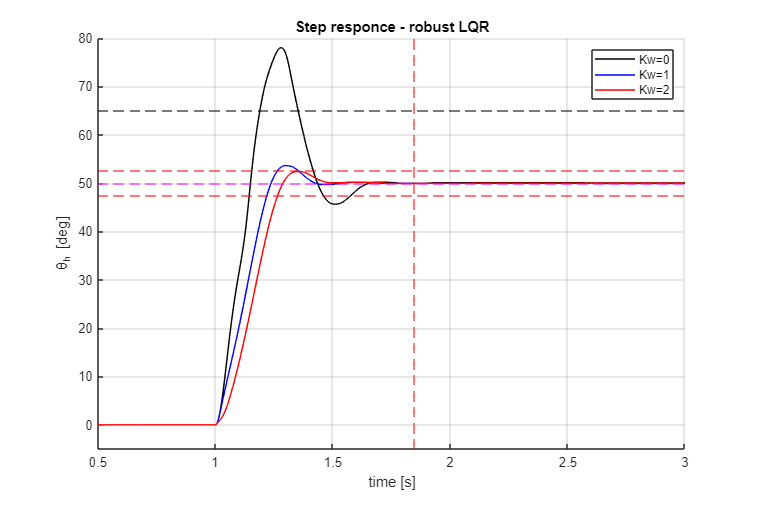

%run simulation
step_size = 50;

ctrl.Kw = 0;
sim('robust_tracking_integral');
data.robust.LQR1.aw1.t    = MotorData.time;
data.robust.LQR1.aw1.thh  = MotorData.signals(1).values;

ctrl.Kw = 1;
sim('robust_tracking_integral');
data.robust.LQR1.aw2.t    = MotorData.time;
data.robust.LQR1.aw2.thh  = MotorData.signals(1).values;

ctrl.Kw = 2;
sim('robust_tracking_integral');
data.robust.LQR1.aw3.t    = MotorData.time;
data.robust.LQR1.aw3.thh  = MotorData.signals(1).values;

figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;
plot(data.robust.LQR1.aw1.t ,data.robust.LQR1.aw1.thh,'k');
plot(data.robust.LQR1.aw2.t ,data.robust.LQR1.aw2.thh,'b');
plot(data.robust.LQR1.aw3.t ,data.robust.LQR1.aw3.thh,'r');
xlabel('time [s]');
ylabel('\theta_h [deg]');
title('Step responce - robust LQR')
xlim([0.5,3])
ylim([-5,80])
yline(50,'m--')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size*1.3,'k--')
xline(1.85,'r--')
legend('Kw=0','Kw=1','Kw=2')
hold off;
grid on

#### Point 7

ctrl.Kw = 1;
step_size = 50;

% max deviations
q11 = logspace(-2, 2, 5);      % {10^-2, 10^-1, ..., 10^2}
th_h_bar = 0.3*step_size*deg2rad;
th_d_bar = (pi/36);
u_bar = 10;

R = 1/u_bar^2;

%run simulation
% first trial q11 = 0.01
Q = diag([1/q11(1)  1/th_h_bar^2   1/th_d_bar^2 0 0]);
Ke = lqr(sysGe,Q,R);
Ki = Ke(1);
sim('robust_tracking_integral.slx');
data.robust.LQR71.t    = MotorData.time;
data.robust.LQR71.thh  = MotorData.signals(1).values;

% second trial q11 = 0.1
Q = diag([1/q11(2)  1/th_h_bar^2   1/th_d_bar^2 0 0]);
Ke = lqr(sysGe,Q,R);
Ki = Ke(1);
sim('robust_tracking_integral.slx');
data.robust.LQR72.t    = MotorData.time;
data.robust.LQR72.thh  = MotorData.signals(1).values;

% third trial q11 = 1
Q = diag([1/q11(3)  1/th_h_bar^2   1/th_d_bar^2 0 0]);
Ke = lqr(sysGe,Q,R);
Ki = Ke(1);
sim('robust_tracking_integral.slx');
data.robust.LQR73.t    = MotorData.time;
data.robust.LQR73.thh  = MotorData.signals(1).values;

% 4th trial, q11 = 10
Q = diag([1/q11(4)  1/th_h_bar^2   1/th_d_bar^2 0 0]);
Ke = lqr(sysGe,Q,R);
Ki = Ke(1);
sim('robust_tracking_integral.slx');
data.robust.LQR74.t    = MotorData.time;
data.robust.LQR74.thh  = MotorData.signals(1).values;

% 5th and last trial, q11 = 100
Q = diag([1/q11(5)  1/th_h_bar^2   1/th_d_bar^2 0 0]);
Ke = lqr(sysGe,Q,R);
Ki = Ke(1);
sim('robust_tracking_integral.slx');
data.robust.LQR75.t    = MotorData.time;
data.robust.LQR75.thh  = MotorData.signals(1).values;

#### Point 8

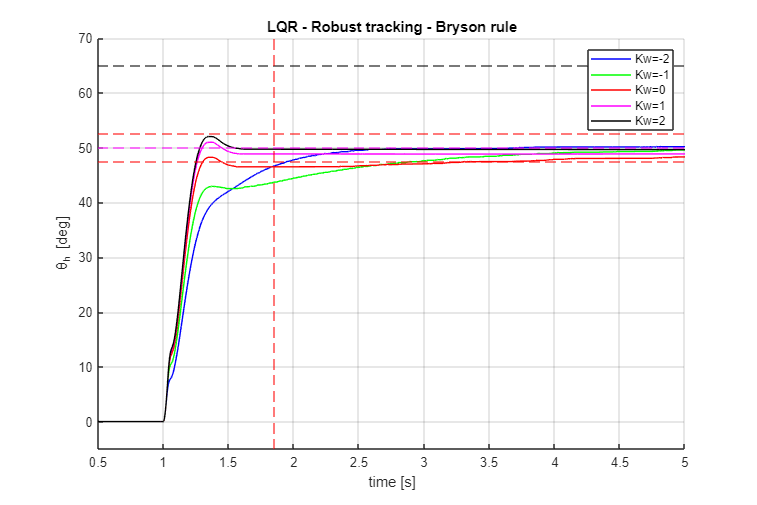

% visualize the simulations
figure('Renderer', 'painters', 'Position', [10 10 900 600])
hold on;

plot(data.robust.LQR71.t, data.robust.LQR71.thh,'b');
plot(data.robust.LQR72.t, data.robust.LQR72.thh,'g');
plot(data.robust.LQR73.t, data.robust.LQR73.thh,'r');
plot(data.robust.LQR74.t, data.robust.LQR74.thh,'m');
plot(data.robust.LQR75.t, data.robust.LQR75.thh,'k');

yline(50,'m--')
xlabel('time [s]');
ylabel('\theta_h [deg]');

title('LQR - Robust tracking - Bryson rule')

yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')
yline(step_size*1.3,'k--')
xline(1.85,'r--')
xlim([0.5,5])
ylim([-5,70])

legend('Kw=-2','Kw=-1','Kw=0', 'Kw=1', 'Kw=2')
hold off
grid on;

data.robust.LQR71.resp = stepinfo(data.robust.LQR71.thh,  data.robust.LQR71.t);
data.robust.LQR72.resp = stepinfo(data.robust.LQR72.thh,  data.robust.LQR72.t);
data.robust.LQR73.resp = stepinfo(data.robust.LQR73.thh,  data.robust.LQR73.t);
data.robust.LQR74.resp = stepinfo(data.robust.LQR74.thh,  data.robust.LQR74.t);
data.robust.LQR75.resp = stepinfo(data.robust.LQR75.thh,  data.robust.LQR75.t);

% display results
response = {'0.01';'0.1';'1';'10';'100'};
settlingTime = {data.robust.LQR71.resp.SettlingTime;  data.robust.LQR72.resp.SettlingTime;  data.robust.LQR73.resp.SettlingTime;
                data.robust.LQR74.resp.SettlingTime ;  data.robust.LQR75.resp.SettlingTime};
overshoot = {data.robust.LQR71.resp.Overshoot;  data.robust.LQR72.resp.Overshoot;   data.robust.LQR73.resp.Overshoot;
             data.robust.LQR74.resp.Overshoot;  data.robust.LQR75.resp.Overshoot};

table(response,settlingTime,overshoot)

ans = 5×3 table
    response    settlingTime    overshoot 
    ________    ____________    __________

    {'0.01'}     {[2.3510]}     {[0.0622]}
    {'0.1' }     {[3.6041]}     {[     0]}
    {'1'   }     {[3.2792]}     {[     0]}
    {'10'  }     {[1.4571]}     {[4.3568]}
    {'100' }     {[1.4708]}     {[4.7843]}


#### point 9

open_system('nominal_tracking_augmentedState.slx')
set_param('nominal_tracking_augmentedState','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

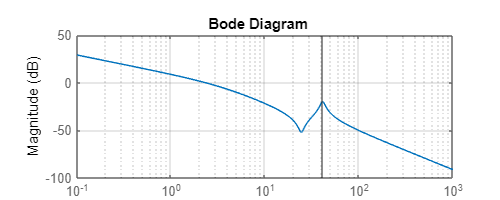

% we need to find the resonant peak
% with bode:
figure('Renderer', 'painters', 'Position', [10 10 500 200])
fband = [20,80];
bodemag(Pu_thh);
[gpeak,fpeak] = getPeakGain(Pu_thh,0.01,fband);
grid on;
hold on;
xline(fpeak);
hold off;

w0 = fpeak

w0 = 41.0269

% or with eigenvalues
abs(eig(A))

ans =    41.0198
   41.0198
    0.0000
    3.4003


th_h_bar = 5*deg2rad;

#### point 10

step_size = 50;
%-------------------------------------------------------------------------- q1
q22 = 0.01;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

KA = lqr(AA, BA, QA,RA);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('nominal_tracking_augmentedState');
data.nominal.LQR_extended.q1.t    = MotorData.time;
data.nominal.LQR_extended.q1.thh  = MotorData.signals(1).values;
data.nominal.LQR_extended.q1.thd  = MotorData.signals(5).values;

%--------------------------------------------------------------------------q2
q22 = 1;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

KA = lqr(AA, BA, QA,RA);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('nominal_tracking_augmentedState');
data.nominal.LQR_extended.q2.t    = MotorData.time;
data.nominal.LQR_extended.q2.thh  = MotorData.signals(1).values;
data.nominal.LQR_extended.q2.thd  = MotorData.signals(5).values;

%-------------------------------------------------------------------------- q3
q22 = 100;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

KA = lqr(AA, BA, QA,RA);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('nominal_tracking_augmentedState');
data.nominal.LQR_extended.q3.t    = MotorData.time;
data.nominal.LQR_extended.q3.thh  = MotorData.signals(1).values;
data.nominal.LQR_extended.q3.thd  = MotorData.signals(5).values;

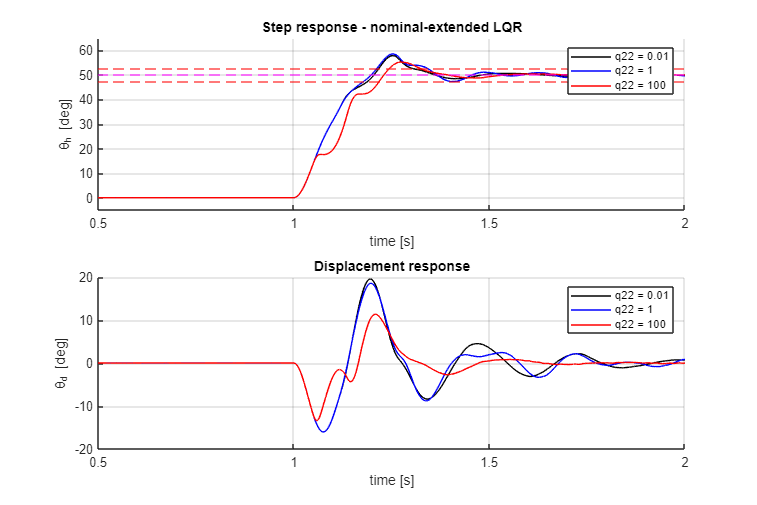


figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.nominal.LQR_extended.q1.t ,data.nominal.LQR_extended.q1.thh,'k');
plot(data.nominal.LQR_extended.q2.t ,data.nominal.LQR_extended.q2.thh,'b');
plot(data.nominal.LQR_extended.q3.t ,data.nominal.LQR_extended.q3.thh,'r');
xlabel('time [s]');
ylabel('\theta_h [deg]');
title('Step response - nominal-extended LQR')
xlim([0.5,2])
ylim([-5,65])
yline(50,'m--')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')

legend('q22 = 0.01','q22 = 1','q22 = 100')
hold off;
grid on

subplot(2,1,2);
hold on;
plot(data.nominal.LQR_extended.q1.t ,data.nominal.LQR_extended.q1.thd,'k');
plot(data.nominal.LQR_extended.q2.t ,data.nominal.LQR_extended.q2.thd,'b');
plot(data.nominal.LQR_extended.q3.t ,data.nominal.LQR_extended.q3.thd,'r');
xlabel('time [s]');
ylabel('\theta_d [deg]');
title('Displacement response')
xlim([0.5,2])

legend('q22 = 0.01','q22 = 1','q22 = 100')
hold off;
grid on

#### point 11

open_system('robust_tracking_integral_augmentedState.slx')
set_param('robust_tracking_integral_augmentedState','SolverType', 'Variable-step', 'Solver', 'ode45', 'StopTime', '5');

AE = [ 0 , CA ; zeros(6,1) , AA];
BE = [0 ; BA];
CE = [0 CA];
qI = 10;
QE = [ qI , zeros(1,6) ; zeros(6,1) , QA];

KE = lqr(AE, BE, QE, RA)

KE = 	1.0e+03 *

    0.0316    0.1168   -0.1079    0.0072    0.0034    7.2676   -4.0989


Ki = KE(1)

Ki = 31.6228

#### Point 12

step_size = 50;
ctrl.Kw = 0.01

ctrl = struct with fields:
               ts5: 0.1500
                Mp: 0.1000
             alpha: 4
    damping_factor: 0.5912
             phi_m: 0.6823
              w_gc: 9.8626
          frq_resp: -0.0778 - 0.0288i
           Delta_K: 12.0593
         Delta_phi: 0.3281
                Kp: 11.4159
                Td: 0.0708
                Ti: 0.2832
                Ki: 40.3035
                Kd: 0.8084
               T_L: 0.0101
                Kw: 0.0100
               T_w: 0.1700


qI = 10;
%-------------------------------------------------------------------------- q1
q22 = 0.01;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

AE = [ 0 , CA ; zeros(6,1) , AA];
BE = [0 ; BA];
CE = [0 CA];
qI = 10;
QE = [ qI , zeros(1,6) ; zeros(6,1) , QA];

KE = lqr(AE, BE, QE, RA);
Ki = KE(1);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('robust_tracking_integral_augmentedState');
data.robust.LQR_extended.q1.t    = MotorData.time;
data.robust.LQR_extended.q1.thh  = MotorData.signals(1).values;
data.robust.LQR_extended.q1.thd  = MotorData.signals(5).values;

%--------------------------------------------------------------------------q2
q22 = 1;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

AE = [ 0 , CA ; zeros(6,1) , AA];
BE = [0 ; BA];
CE = [0 CA];
qI = 10;
QE = [ qI , zeros(1,6) ; zeros(6,1) , QA];

KE = lqr(AE, BE, QE, RA);
Ki = KE(1);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('robust_tracking_integral_augmentedState');
data.robust.LQR_extended.q2.t    = MotorData.time;
data.robust.LQR_extended.q2.thh  = MotorData.signals(1).values;
data.robust.LQR_extended.q2.thd  = MotorData.signals(5).values;

%-------------------------------------------------------------------------- q3
q22 = 100;

%state space realization (AQ',BQ',CQ',DQ')
AQ_prime = [0 1; -w0^2 0];
BQ_prime = [0; 1];
CQ_prime = [sqrt(q22)*w0^2, 0];
DQ_prime = 0;

%state space realization (AQ,BQ,CQ,DQ)
AQ = AQ_prime;
zer = zeros(2,1);
BQ = [zer BQ_prime, zeros(2,2)];
CQ = [zer';CQ_prime; zeros(2,2)];
DQ = diag ( [1/th_h_bar , DQ_prime , 0, 0]);

%augmented state model (AA,BA,CA,DA) BISOGNA USARE Ad Bd ecc o A B...penso Ad
zer = zeros(4,2);
AA = [Ad zer; BQ AQ];
BA = [Bd ; 0 ; 0];
CA = [Cd 0 0];
DA = 0;

%cost matrices
QA = [DQ.'*DQ, DQ.'*CQ; CQ.'*DQ, CQ.'*CQ];
NA = zeros(8,1);
RA = R;

AE = [ 0 , CA ; zeros(6,1) , AA];
BE = [0 ; BA];
CE = [0 CA];
qI = 10;
QE = [ qI , zeros(1,6) ; zeros(6,1) , QA];

KE = lqr(AE, BE, QE, RA);
Ki = KE(1);

S = [AA,BA;CA,DA];
b=[0 0 0 0 0 0 1]';
N = linsolve(S,b); %Sx=b
N_x = [N(1) N(2) N(3) N(4) N(5) N(6)];
N_u = N(7);

sim('robust_tracking_integral_augmentedState');
data.robust.LQR_extended.q3.t    = MotorData.time;
data.robust.LQR_extended.q3.thh  = MotorData.signals(1).values;
data.robust.LQR_extended.q3.thd  = MotorData.signals(5).values;

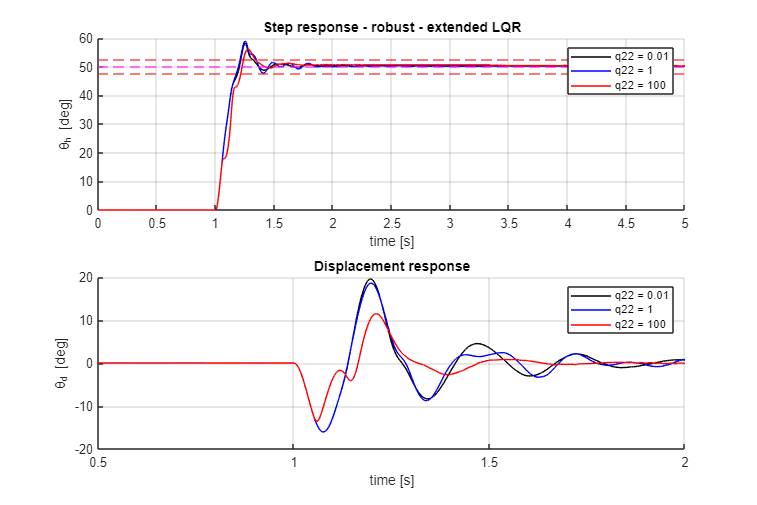


figure('Renderer', 'painters', 'Position', [10 10 900 600])
subplot(2,1,1);
hold on;
plot(data.robust.LQR_extended.q1.t ,data.robust.LQR_extended.q1.thh,'k');
plot(data.robust.LQR_extended.q2.t ,data.robust.LQR_extended.q2.thh,'b');
plot(data.robust.LQR_extended.q3.t ,data.robust.LQR_extended.q3.thh,'r');
xlabel('time [s]');
ylabel('\theta_h [deg]');
title('Step response - robust - extended LQR')
% xlim([0.5,20])
% ylim([-5,65])
yline(50,'m--')
yline(step_size*1.05,'r--')
yline(step_size*0.95,'r--')

legend('q22 = 0.01','q22 = 1','q22 = 100')
hold off;
grid on

subplot(2,1,2);
hold on;
plot(data.robust.LQR_extended.q1.t ,data.robust.LQR_extended.q1.thd,'k');
plot(data.robust.LQR_extended.q2.t ,data.robust.LQR_extended.q2.thd,'b');
plot(data.robust.LQR_extended.q3.t ,data.robust.LQR_extended.q3.thd,'r');
xlabel('time [s]');
ylabel('\theta_d [deg]');
title('Displacement response')
xlim([0.5,2])

legend('q22 = 0.01','q22 = 1','q22 = 100')
hold off;
grid on

## ESTIMATION

%initial param
initia_deflection = 20;
Jb = 1.4e-3;


Phi = [-1,1 ; -2,1 ; -3,1 ; -4,1 ; -5,1 ; -6,1 ;];
Y = [log(abs()) log(abs()) log(abs()) log(abs()) log(abs()) log(abs())];

Error using abs
Not enough input arguments.

THLS = Phi\Y

%open simulink
%load elasticjoint

yabs = abs(elasticJoint.thd);

Unable to resolve the name elasticJoint.thd.

%[pks,locs] = findpeaks(elasticJoint.thd);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(elasticJoint.t,elasticJoint.thd)
hold on
plot(elasticJoint.t,yabs)
%plot(locs,pks,'g--')
hold off
legend('')
Phi = [-1,1 ; -2,1 ; -3,1 ; -4,1 ; -5,1 ; -6,1];
Y = [log(abs(20)) ; log(abs(17.54)) ; log(abs(16.73)) ; log(abs(14.4)) ; log(abs(13.43)) ; log(abs(12.72))];
THLS = Phi\Y;
csi = THLS(1);
damp_hat = csi/ sqrt(pi^2 + csi^2);
wk_hat = pi/(1.39-1.13);

w_hat = mean(wk_hat);
wn_hat = wk_hat/sqrt(1 - damp_hat^2);

Bb_hat = Jb * (2*damp_hat*wn_hat)
K_hat = Jb * wn_hat^2

















